# Bernoulli Equation

[⇦ Overview](matlab:open('./Overview.html'))

The Bernoulli equation, often refered as Bernoulli's principle is a fundamental principle in flui dynamics that describes the relationship between pressure, velocity and elevation of the fluid. 

[Catchy Image]

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

The Bernoulli equation is a fundamental concept in fluid mechanics and is sued to describe the relationship between pressure, velocity and elevation change in a fluid system. This equation is named after the Swiss mathematician, Daniel Bernoulli, who first formulated it in 1738. In this script we will explore the basics principles of the Bernoulli equation and its applications in various fields surch as aerodynamics and hydrodynamics.

## Bernoulli's equation

The Bernoulli equation states that the total energy of a fluid system is constant along a streamline:


$$P+
\frac{1}{2}\rho v^2+
\rho g h= \text{Constant} \qquad(\star)$$


where P represents the pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration and $h$ the elevation. From a non-expert point of view, the conservation of "energy" promised by the definition is not evident. In order to highlight the energy term, we can multiply both side of $(\star)$ by the volume $V$ (careful with the definition of the fluid's velocity and its volume $v \neq V$):


$$PV+
\frac{1}{2}\rho V v^2+
\rho V g h= \text{Constant} \qquad(\star)\times V$$


with $\rho V = m$, the fluid mass, we obtain:


$$PV+
\frac{1}{2}mv^2+
m g h= \text{Constant} \qquad(\star)\times V$$


- $PV$    is the pressure potential energy

- $\frac{1}{2}mv^2$    is the kinetic energy

- $mgh$    is the gravitational potential energy

So the $(\star)$ is in fact the conservation of the total energy along a stream line. We should now apply the Bernoulli equation along a streamline of a free flowing fluid.

  **Try.** Use the slider below to visualize a streamline in between point A and point B of a fluid flow with an elevation difference.

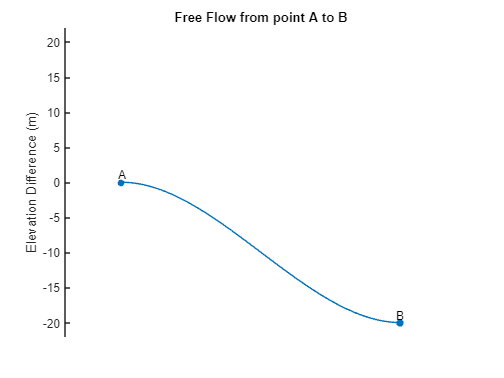

dh = -20;
plotFreeFlow(double(dh))

The fluid is considered : 

- incompressible ( $\rho=\text{Constant}$ )

- at point A, it has a velocity $v_a$, pressure $P_a = 101,325$ Pa, and its elevation 0 m

- at point B, it has a velocity $v_b$, pressure $P_b$, and its elevation is `dh` m

syms P_A v_A P_B v_B g rho
u = symunit;
g = 9.81*u.m/u.s^2

$$g = \frac{981}{100}\,\frac{m}{s^{2}}$$

dh = dh*u.m

$$dh = -20\,m$$

P_A = 101325*u.Pa

$$P\_A = 101325\,\mathrm{Pa}$$

  **Try.** Select the fluid:

rho = 1000*u.kg/u.m^3

$$rho = 1000\,\frac{\mathrm{kg}}{m^{3}}$$

   **Exercise. **Write the total energy at point A as in $(\star)$ and store the results in `E_A`

E_A = P_A + 1/2*rho*v_A + rho*g*0

$$E\_A = 101325\,\mathrm{Pa}+500\,v_{A}\,\frac{\mathrm{kg}}{m^{3}}$$

 **Exercise. **Write the total energy at point B as in $(\star)$ and store the results in `E_B`

E_B = P_B + 1/2*rho*v_B + rho*g*dh

$$E\_B = P_{B}-196200\,\frac{\mathrm{kg}}{m\,s^{2}}+500\,v_{B}\,\frac{\mathrm{kg}}{m^{3}}$$

 **Exercise. **Write the equilibrium along the streamline

Eqn = E_B == E_A

$$Eqn = P_{B}-196200\,\frac{\mathrm{kg}}{m\,s^{2}}+500\,v_{B}\,\frac{\mathrm{kg}}{m^{3}}=101325\,\mathrm{Pa}+500\,v_{A}\,\frac{\mathrm{kg}}{m^{3}}$$

 **Exercise. **Explore the following scenario

    1. The velocity is constant ( $v_A=v_B$ ), how does the pressure evolves from A to B depending the on the elevation change?

P_B = solve(Eqn,P_B)

$$P\_B = 101325\,\mathrm{Pa}+196200\,\frac{\mathrm{kg}}{m\,s^{2}}+500\,v_{A}\,\frac{\mathrm{kg}}{m^{3}}-500\,v_{B}\,\frac{\mathrm{kg}}{m^{3}}$$

    2. The elevation change are negligeable ( $\Delta h = 0$ ), how does the velocity evolves depending on the pressure change from A to B?

    3. Fuid has constant velocity, dh is positive

The Bernoulli equation $(\star)$ is often writen in the different form, called the hydraulic head form:


$$\frac{P}{\rho g} + \frac{V^2}{2 g} + h = H_0=\text{Constant}$$


The equation stays the same in nature, but the different term are all writen in unit of length instead of being writen in unit of pressure. This form is used in the case of hydraulic flow (flow of water) where the density of the fluid is high and any change in elevation impact the flow. While dealing with gases, the $(\star)$ is preferred as the effect of gravity are often neglected.

Because all of the term in $(\star)$ are dimensionally equivalent to a pressure, we are defining different pressures:

- $P$ is the static pressure.

- $\frac{1}{2}\rho U^2$    is the dynamic pressure, it is pressure that is exerted by the fluid dur to its motion. It is also known as "impact pressure". 

[Image of someone taking a shower] vs [someone impacted by a jet]

- $\rho g h$ is the hydrostatic pressure

The total pressure is defined as the sum of the static, dynamic and hydrostatic pressure:


$$P_\text{total} = P + \frac{1}{2}\rho U^2 + \rho g h$$


Therefore, Bernoulli's equation can be read as the conservation of total pressure along a streamline. Finally, the stagnation pressure is defined as:


$$P_\text{stagnation} = P + \frac{1}{2}\rho U^2$$


The stagnation pressure is equivalent to the pressure that the fluid would have if it came to "stagnation" (a.k.a. $U=0$). It is obtained from applying $(\star)$ as:


$$ P + \frac{1}{2}\rho U^2 = P_\text{stagnation} + \frac{1}{2}\rho 0^2$$


XXX Plot free flow again, next to pressure plot along x, P_tot, 

## **Ideal Flow Pipe**

### **Converging pipe**

### **Diverging pipe**

***Introducing Flow.app***

## **Wind turbine**

[catchy image wind turbine]

**What is power in?**

% syms V_in rho
% E_in = 1/2*rho*V_in^2

**What is power out?**

% syms V_out
% E_out = 1/2*rho*V_out^2

**What is the mass flow through the turbine?**

% m_dot = 1/2*(V_in+V_out)

## **Measurment tools developed with Bernoulli**

### **Venturi tube**

[Image venturi tube]

% 

### **Pitot tube**

[Drawing pitot tube]

% 

## **Airfoil**

**Used for Cessna 172R**

% [lc,lu,ll] = NACAXXXX(12,2,40);
% CruiseSpeed = 135; % (kts)
% g = 9.81;
% Mass = 970; % (kg)
% v0 = 0.514444 * CruiseSpeed;
% Rho = 1.1768;
% Area = 16.1651;
% Chords = Area/9.6;

% Cl = Mass*g / (0.5*Rho*v0^2*Area)

% t0 = Chords/v0;
% vu = lu*Chords/t0;
% vl = ll*Chords/t0;
% Cl = (vu^2-vl^2)/v0^2

## Lexical

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the line in a flow that is tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane. 

function plotFreeFlow(dh)
arguments
    dh (1,1) {mustBeReal,mustBeInRange(dh,-20,20)} = 0
end    

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dh*(2*xl.^3-3*xl.^2);

    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    scatter(ax,0,0,30,'filled',SeriesIndex=1)
    text(0,0,"A",HorizontalAlignment="center",VerticalAlignment="bottom")
    hold on

    % Plot B:
    scatter(ax,1,dh, 'filled',SeriesIndex=1)
    text(1,dh,"B",HorizontalAlignment="center",VerticalAlignment="bottom")

    % Plot Free Path:
    plot(ax,xl,yl)
    hold off

    % Set plot limit, title, etc.:
    xlim([-0.2 1.2])
    ylim([-22 22])
    title("Free Flow from point A to B")
    ylabel("Elevation Difference (m)")
    ax.XAxis.Visible = "off";
    
end

[⇦ Return to the navigation page](matlab:open('./Overview.html'))